**GENERATE SCATTERED FIELD**

This script computes the scattered electromagnetic field for a 2-D microwave imaging scenario.

The scattered field is defined as:

-   Es = Et - Ei

where:

-   Et    :    total field (DOI with dielectric target present)

-   Ei    :    incident field (homogeneous DOI, no target)

-   Es    :    scattered field (caused by the target contrast)

Both Et and Ei are computed on a NEW mesh, independent of the mesh used in generate_background_field. This script is organized as follows:

- The geometry.mat file is loaded only to recover the geom struct (geometry parameters)

- A new mesh is generated with different element sizes

- The incident field is recomputed on this new mesh

- The total field is computed

clc;
close all;
clear;
addpath('lib');

**LOAD GEOMETRY PARAMETERS**

Only the geom struct is needed from geometry.mat to define the spatial layout of the scenario (DOI radius, antenna ring, target position, etc.).

load('results/geometry.mat', 'geom');

**PHYSICAL CONSTANTS**

  mu0    :    vacuum permeability

  eps0    :    vacuum permittivity

  c0        :    speed of light in vacuum

mu0  = 4*pi*1e-7;
eps0 = 8.854187817e-12;
c0 = 1/sqrt(mu0*eps0);

**OPERATING FREQUENCY**

The simulation frequency must match the one used in generate_background_field.

sim.f = 1e9;
sim.omega = 2*pi*sim.f;

**MATERIAL DEFINITIONS**

Three electromagnetic regions are defined. Background and DOI properties must match those used in generate_background_field exactly.

The target is assigned different dielectric properties from the DOI, creating the electromagnetic contrast.

The complex relative permittivity is modeled as:

-   eps_complex = eps_r - j*sigma/(omega*eps0)

where:

-   eps_r    :    relative dielectric permittivity

-   sigma    :    electrical conductivity

% Background Material

materials.background.epsr  = 20;
materials.background.sigma = 0.01;

% DOI Material

materials.doi.epsr  = 40;
materials.doi.sigma = 0.02;

% Embedded Target Material
% The target has different dielectric properties from the DOI,
% creating electromagnetic contrast (scattering).

materials.target.epsr  = 60;
materials.target.sigma = 0.5;

% Complex Permittivity Computation

materials.background.epsc = ...
    materials.background.epsr ...
    - 1i*materials.background.sigma/(sim.omega*eps0);

materials.doi.epsc = ...
    materials.doi.epsr ...
    - 1i*materials.doi.sigma/(sim.omega*eps0);

materials.target.epsc = ...
    materials.target.epsr ...
    - 1i*materials.target.sigma/(sim.omega*eps0);

**MESH CONTROL PARAMETERS**

A mesh with different element sizes is used here. This ensures that the scattered field data is generated on a discretisation that is independent of the one used in generate_background_field (avoiding the inverse crime).

Rule of thumb:

-   lambda / 10    :    minimum acceptable

-   lambda / 12    :    good FEM accuracy

-   lambda / 15    :    high accuracy

lambda_doi = c0/(sim.f*sqrt(materials.doi.epsr));
lambda_bg  = c0/(sim.f*sqrt(materials.background.epsr));

% Different element sizes from generate_background_field to avoid inverse crime

meshControl.hDOI    = lambda_doi/15;
meshControl.hBG     = lambda_bg/10;
meshControl.hAnt    = lambda_bg/15;
meshControl.hTarget = lambda_doi/15;

% Antenna Circle Radius

meshControl.rAnt = meshControl.hAnt;

**CREATE SCENARIO AND FEM MESH**

The function createScenarioMesh() builds the mesh used for both the incident and total field computations.

scenario = createScenarioMesh(geom, meshControl);

**GEOMETRY VISUALIZATION**

Verify the mesh topology before running the forward solvers.

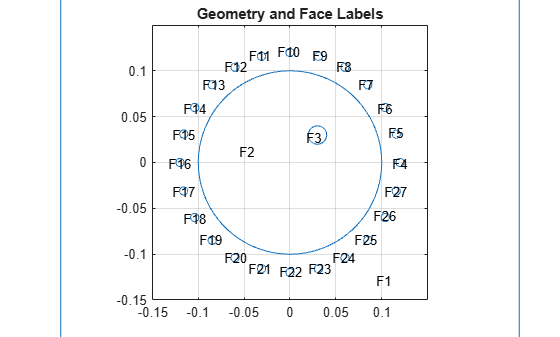

plotGeometry(scenario.model);
xlim([-0.15 0.15]);
ylim([-0.15 0.15]);

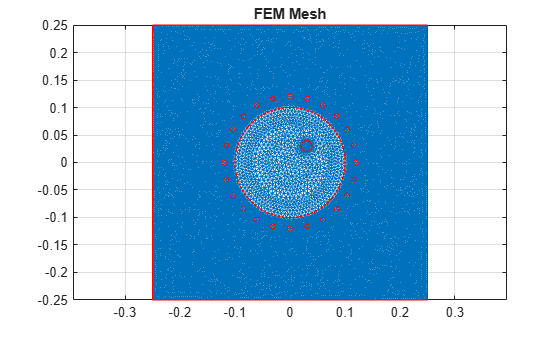

plotMesh(scenario.model);

**MATERIAL ASSIGNMENT TO FEM CELLS**

Two permittivity maps are assigned on the new mesh:

- perm_bg    :    homogeneous DOI (target = DOI properties) used for the incident field

- perm_tot    :    DOI with target contrast used for the total field

% Homogeneous DOI, no target contrast
materials_bg = materials;
materials_bg.target.epsr  = materials.doi.epsr;
materials_bg.target.sigma = materials.doi.sigma;
materials_bg.target.epsc  = materials.doi.epsc;

perm_bg = assignPermittivity(...
    scenario.centroids,...
    geom,...
    materials_bg);

% DOI with target contrast
perm_tot = assignPermittivity(...
    scenario.centroids,...
    geom,...
    materials);

**PERMITTIVITY VISUALIZATION**

Verify that perm_tot shows a distinct target region while perm_bg is homogeneous inside the DOI.

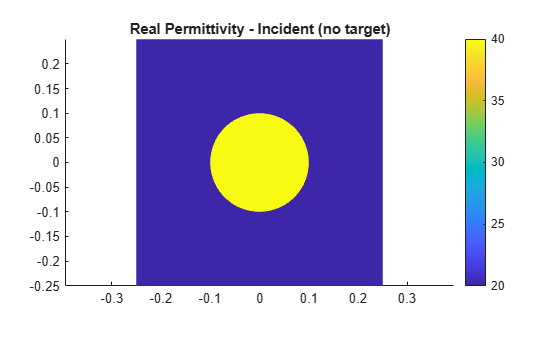

plotPermittivity(...
    scenario.mesh,...
    perm_bg.real,...
    'Real Permittivity - Incident (no target)');

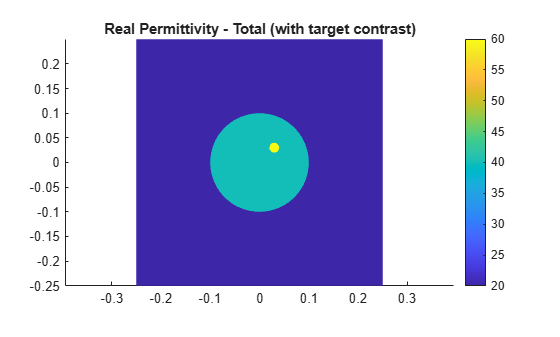


plotPermittivity(...
    scenario.mesh,...
    perm_tot.real,...
    'Real Permittivity - Total (with target contrast)');

**ANTENNA NODE IDENTIFICATION**

Each antenna position is projected onto the nearest FEM node of the new mesh.

probeNodes = findProbeNodes(...
    scenario.mesh.Nodes,...
    scenario.antennaPositions);

**FORWARD FEM SOLUTION**

The function fem2d() computes the electromagnetic field for both scenarios generated by the antenna array inside the heterogeneous dielectric medium.

current = 1e-3;

% Incident field homogeneous DOI
[Everts_i, Ecells_i, ] = fem2d(...
    scenario.mesh.Nodes',...
    scenario.mesh.Elements',...
    perm_bg.complex,...
    sim.f,...
    probeNodes,...
    materials.background.epsc,...
    [], current);

% Total field homogeneous DOI
[Everts_t, Ecells_t, Area] = fem2d(...
    scenario.mesh.Nodes',...
    scenario.mesh.Elements',...
    perm_tot.complex,...
    sim.f,...
    probeNodes,...
    materials.background.epsc,...
    [], current);

Ecells_sct = Ecells_t - Ecells_i;
Eprobes_i = Everts_i(probeNodes,:);
Eprobes_t = Everts_t(probeNodes,:);

**FIELD VISUALIZATION**

The electric fields generated by one transmitting antenna are visualized:

- Incident field magnitude and phase

- Total field magnitude and phase

- Scattered field magnitude and phase

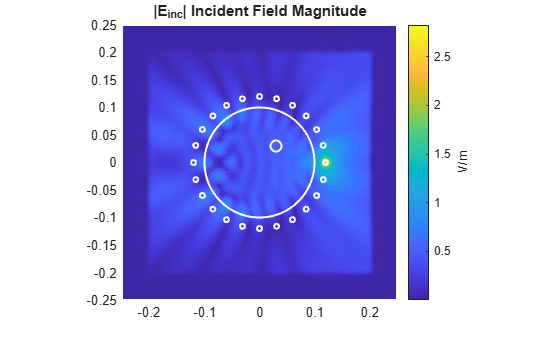

selectedAntenna = 1;

plotField(...
    scenario,...
    abs(Ecells_i(:, selectedAntenna)),...
    '|E_{inc}| Incident Field Magnitude','V/m');

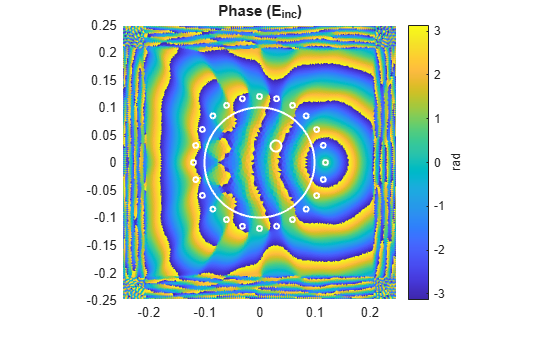

plotField(...
    scenario,...
    angle(Ecells_i(:, selectedAntenna)),...
    'Phase (E_{inc})','rad');

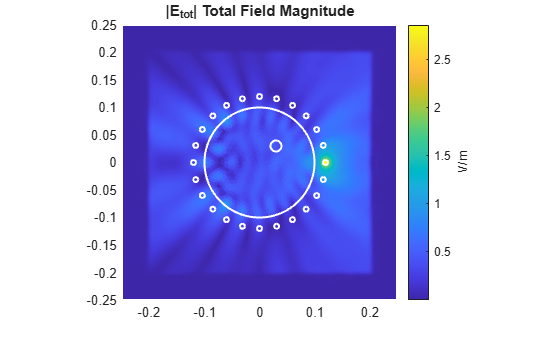


plotField(...
    scenario,...
    abs(Ecells_t(:, selectedAntenna)),...
    '|E_{tot}| Total Field Magnitude','V/m');

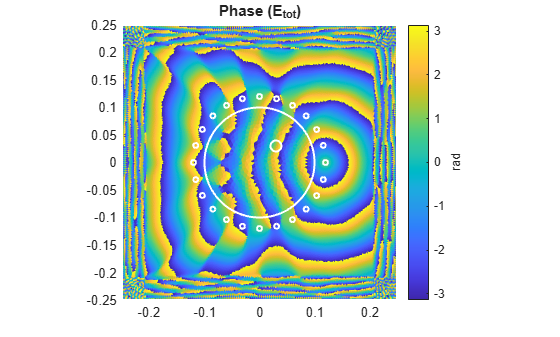

plotField(...
    scenario,...
    angle(Ecells_t(:, selectedAntenna)),...
    'Phase (E_{tot})','rad');

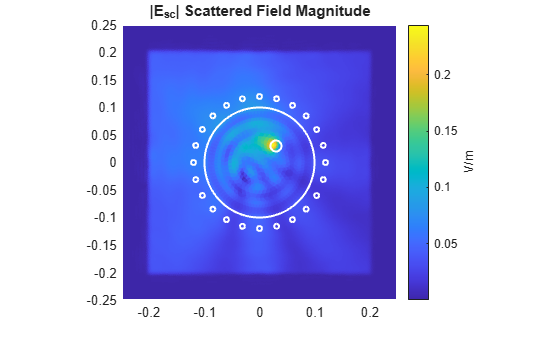


plotField(...
    scenario,...
    abs(Ecells_sct(:, selectedAntenna)),...
    '|E_{sc}| Scattered Field Magnitude','V/m');

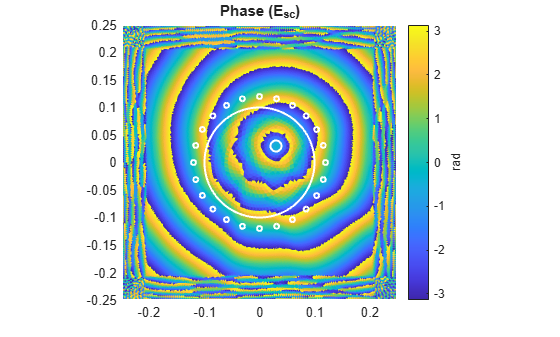

plotField(...
    scenario,...
    angle(Ecells_sct(:, selectedAntenna)),...
    'Phase (E_{sc})','rad');

**SAVE RESULTS**

Two files are exported:

- scattered_fields.mat

- scattered field matrix and supporting field data

- geometry_sf.mat

- new mesh data used for data generation

nameSF  = 'results/scattered_fields';
nameGEO = 'results/geometry_sf';

freq = sim.f;

save([nameSF, '.mat'],...
    'Everts_t',...
    'Everts_i',...
    'perm_tot',...
    'current',...
    'freq');

% Save new mesh geometry (different from geometry.mat used for reconstruction)

verts_sf      = scenario.mesh.Nodes';
cells_sf      = scenario.mesh.Elements';
Ind_probes_sf = probeNodes;

save([nameGEO, '.mat'],...
    'verts_sf',...
    'cells_sf',...
    'Ind_probes_sf',...
    'geom');